# **drawArcArrow**

Draw the arc arrow between two points.

## Description

Draw arc arrow between two points. Arrowhead is drawn at end point if form > 0 and at start point if form<0. Arrowhead types are taken from IGES 5.3,  4.62 Leader (arrow) entity, pp 259-251 ([1]).  

## Syntax

drawArcArrow( form, ad1, ad2, xc, yc, r, sang, ang)

drawArcArrow( __, LineSpec)

p = drawArcArrow( __)

## Description

drawArcArrow( form, ad1, ad2, xc, yc, r, sang, ang)  draw arrow between given points. 

drawArcArrow( form, ad1, ad2, xc, yc, r, sang, ang, [LineSpec](https://www.mathworks.com/help/matlab/ref/linespec.html))  set line specification.

## Method

drawArcArrow use function **drawArrowhead**  to draw arrowhead. 

## Arguments

### Input Arguments

**form **- arrowhead type number: 1,...,12 ([1]). If form > 0 then arrow head point is the end point i.e. the arrow is directed from (x1,y1), given by sang  to (x2,y2) given by ang,(see Example 1) if form < 0 then the start point is the arrow tail i.e. the arrow is directed from (x2,y2) to (x1,y1) (see Example 2).

   Form Meaning

-      Wedge

-      Triangle

-      Filled Triangle

-      No Arrowhead

-      Circle

-      Filled Circle

-      Rectangle

-      Filled Rectangle

-      Slash

-      Integral Sign 

-      Open Triangle

-      Dimension Origin

**ad1 **- arrowhead height (>0)

**ad2 **- arrowhead width (>0)

**xc, yc **-  center

**r **- radius

**sang **- start angle in degrees. The start point (x1,y1):  x1 = xc + r*cos(sang), y1 = yc + r*sin(sang)..

**ang ** - [central angle](https://en.wikipedia.org/wiki/Central_angle) (arc's angular distance) in degrees: >0 is CCLW, <0 is CCW. The end point is (x2,y2): x2 = xc + r*cos(sang+ang),.y2=yc + r*sin(sang+ang)..

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional output:

**p** - structure with fields

p.xk, p.yk - key points: 1=start, 2 = end

p.color - line color

## Examples

### Example 1 

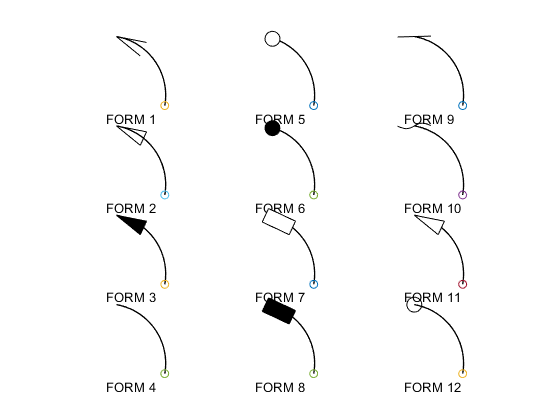

figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad2 = 0.5/2;
for n = 1:12
    y = y - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    % is arrowhead is at end point becouse form > 0
    sang = -10;
    ang = 90;
    r = 1;
    p = drawArcArrow(n,ad1,ad2,x,y,r,sang,ang);
    scatter(p.xk(1),p.yk(1))
    text(x,y-dy/4,sprintf('FORM %d',n))
    k = k + 1;
    if k > 3
        k = 0;
        x = x + dx;
        y = 3*dy;
    end
end
axis off

### Example 2

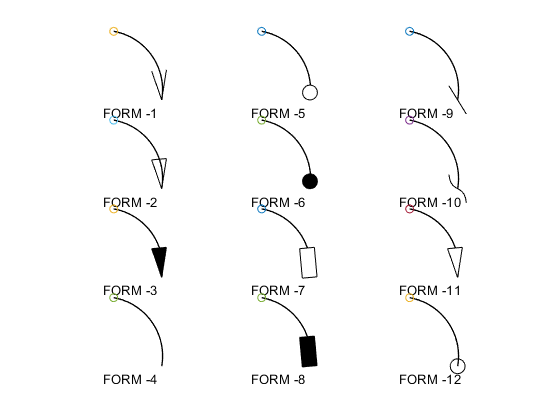

figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad2 = 0.5/2;
for n = 1:12
    y = y - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    % is arrowhead is at start point becouse form < 0
    sang = -10;
    ang = 90;
    r = 1;
    p = drawArcArrow(-n,ad1,ad2,x,y,r,sang,ang);
    scatter(p.xk(1),p.yk(1))
    text(x,y-dy/4,sprintf('FORM %d',-n))
    k = k + 1;
    if k > 3
        k = 0;
        x = x + dx;
        y = 3*dy;
    end
end
axis off

### Example 3

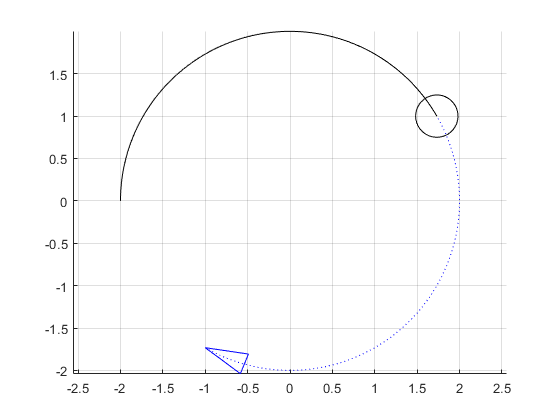

figure
hold on
axis equal
ad1 = 0.5;
ad2 = ad1/2;
drawArcArrow(  2,ad1,ad2,0,0,2,30,-150,'b:') % linestyle does not affect arrowhead
drawArcArrow(-12,ad1,ad1,0,0,2,30,150,'k')
grid on

## **See Also**

## References

  [1] [IGES Initial Graphics Exchange Specification IGES 5.3](http://paulbourke.net/dataformats/iges/IGES.pdf)